# HexaMotor — Closed-Loop System Identification and PI Velocity Design

*Live demo based on the HexaMotor lab manuals "Position Control V02" and "Velocity Control V02".*

This script walks through the whole modelling-to-control chain:

- The DC-motor equations (second-order electromechanical model) and the first-order approximation.

- The canonical second-order system and its performance metrics.

- The **closed-loop second-order identification method**: a motor under proportional *position* feedback behaves as a canonical second-order system, so identifying $\zeta$ and $\omega_n$ yields the motor gain $k_m$ and time constant $\tau$.

- **Experiment 1** — a chirp frequency sweep on `HexaMotor_Position_Control_V02.slx`, identified with `tfest`.

- **Experiment 2** — a velocity step with $K_p=1,\ K_i=0$ on `HexaMotor_Velocity_Control_V02.slx`.

- A PI design for **30 % overshoot** at the **200 Hz** controller rate.

- **Experiment 3** — the designed PI on the setup, compared with the first run and with simulation.

## 0. Demo settings

- **Recorded sweep** — Experiment 1 uses `FrequencyResponse.mat`, a chirp recorded on a real HexaMotor; the velocity steps run on the motor emulator. No hardware needed.

- **Hardware** — every experiment runs on the HexaMotor (Arduino MKR Zero, Monitor & Tune / external mode). While each run executes, the Simulink model and its Scope open beside the Live Editor and the Scope streams the reference and response live from the board.

- **Virtual motor** — every experiment runs on a built-in nonlinear motor emulator (Coulomb friction, stiction, encoder quantization, PWM resolution, 12 V saturation).

runMode = "rec";
KpPos = 10;

fs = 200;             % controller sample rate [Hz]
Ts = 1/fs;            % sample time [s]
sampleRate = Ts;      % base-workspace variable used by both Simulink models (it is a sample TIME)
posModel = "HexaMotor_Position_Control_V02";
velModel = "HexaMotor_Velocity_Control_V02";
s = tf('s');
LPF = 1/(0.05*s + 1); % velocity-measurement filter inside the models (Filtered Derivative, T = 0.05 s)
if runMode == "hw", measLabel = "Measured"; else, measLabel = "Emulated"; end
fprintf("Mode: %s | fs = %g Hz (Ts = %g ms) | position-loop Kp = %g\n", runMode, fs, 1e3*Ts, KpPos);

Mode: rec | fs = 200 Hz (Ts = 5 ms) | position-loop Kp = 10


## 1. DC-motor equations

Armature (electrical) and rotor (mechanical) equations, with viscous and Coulomb friction:


$$V = R\,i + L\frac{di}{dt} + K_b\,\omega \qquad\qquad K_T\,i = J\frac{d\omega}{dt} + B\,\omega + T_{\mathrm{coulomb}}$$


Eliminating the current (and treating Coulomb friction separately, it is compensated in the models by a ±0.35 V feed-forward) gives the **second-order motor equation**:


$$LJ\,\frac{d^2\omega}{dt^2} + (RJ + BL)\frac{d\omega}{dt} + (BR + K_TK_b)\,\omega = K_T\,V$$



$$G_\omega(s) = \frac{\Omega(s)}{V(s)} = \frac{K_T}{LJ\,s^2 + (RJ+BL)\,s + (BR + K_TK_b)}$$


The electrical pole ($\approx R/L$) is far faster than the mechanical pole, so with $L \approx 0$ we get the **first-order approximation** used for control design:


$$G(s) = \frac{k_m}{\tau s + 1}, \qquad k_m = \frac{K_T}{BR + K_TK_b}\;\left[\frac{rad/s}{V}\right], \qquad \tau = \frac{RJ}{BR + K_TK_b}\;[s]$$


Position is the integral of velocity, so the voltage-to-angle plant is $P(s) = \frac{\Theta(s)}{V(s)} = \frac{k_m}{s(\tau s + 1)}$.

## 2. Canonical second-order system


$$T(s) = \frac{K}{s^2 + 2\zeta\omega_n s + \omega_n^2}$$


For $\zeta<1$ the step-response metrics are


$$\%OS = 100\,e^{-\pi\zeta/\sqrt{1-\zeta^2}}, \qquad T_p = \frac{\pi}{\omega_n\sqrt{1-\zeta^2}}, \qquad T_s \approx \frac{4}{\zeta\omega_n}, \qquad T_r \approx \frac{1.8}{\omega_n}$$


and they can be inverted — measure $OS$ and $T_p$, get back $\zeta$ and $\omega_n$:


$$\zeta = \frac{-\ln(OS)}{\sqrt{\pi^2 + \ln^2(OS)}}, \qquad \omega_n = \frac{\pi}{T_p\sqrt{1-\zeta^2}}$$


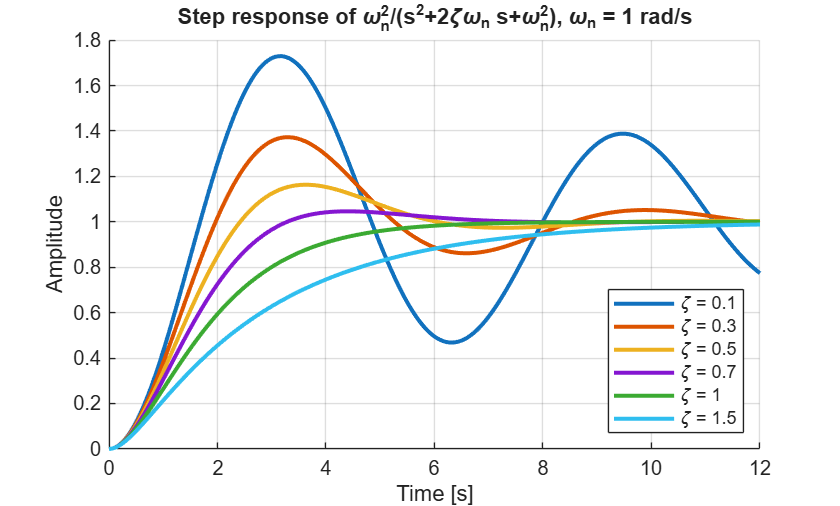

wn = 1;
dampingRatios = [0.1 0.3 0.5 0.7 1 1.5];
tt = 0:0.01:12;
figure
hold on
for zeta = dampingRatios
    plot(tt, step(tf(wn^2, [1 2*zeta*wn wn^2]), tt), LineWidth=2, DisplayName="\zeta = " + zeta);
end
hold off
grid on
legend(Location="southeast")
title("Step response of \omega_n^2/(s^2+2\zeta\omega_n s+\omega_n^2), \omega_n = 1 rad/s")
xlabel("Time [s]"); ylabel("Amplitude")

## 3. Closed-loop second-order identification method

Close a proportional position loop around the motor:


$$T(s) = \frac{K_pP(s)}{1+K_pP(s)} = \frac{K_pk_m/\tau}{s^2 + \frac{1}{\tau}s + \frac{K_pk_m}{\tau}}$$


Matching to the canonical form: $2\zeta\omega_n = 1/\tau$ and $\omega_n^2 = K_pk_m/\tau$, therefore


$$\tau = \frac{1}{2\zeta\omega_n}, \qquad k_m = \frac{\omega_n^2\,\tau}{K_p}$$


With $K_p$ known, anything that gives $\zeta$ and $\omega_n$ of the closed loop identifies the open-loop motor. The lab uses two routes:

- **Step response**: measure $\%OS$ and $T_p$ → invert the formulas above.

- **Frequency response (chirp)**: fit a 2-pole, 0-zero model with `tfest` → read $\omega_n^2$ and $2\zeta\omega_n$ straight from the denominator.

**Pre-lab sanity check** — the step route on the nominal motor $G(s)=\frac{2.5}{0.1s+1}$ must give back $k_m=2.5$ and $\tau=0.1$:

P0 = 2.5/(s*(0.1*s + 1));
T0 = feedback(KpPos*P0, 1);
si = stepinfo(T0);
OS = si.Overshoot/100;
Tp = si.PeakTime;
zeta0 = -log(OS)/sqrt(pi^2 + log(OS)^2);
wn0 = pi/(Tp*sqrt(1 - zeta0^2));
tau0 = 1/(2*zeta0*wn0);
km0 = wn0^2*tau0/KpPos;
fprintf("OS = %.1f %%, Tp = %.3f s  ->  zeta = %.3f, wn = %.2f rad/s  ->  km = %.3f, tau = %.4f s\n", ...
    100*OS, Tp, zeta0, wn0, km0, tau0);

OS = 35.1 %, Tp = 0.212 s  ->  zeta = 0.316, wn = 15.63 rad/s  ->  km = 2.470, tau = 0.1011 s


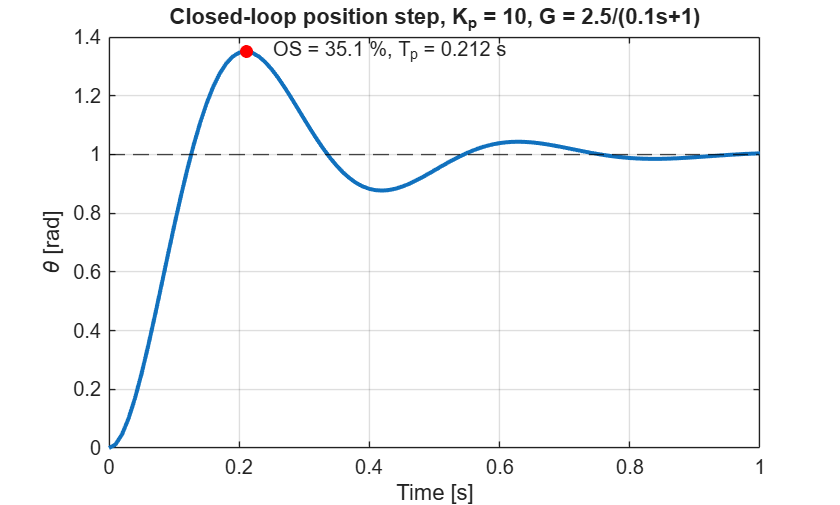

[y0, t0] = step(T0, 1);
figure
plot(t0, y0, LineWidth=2); hold on
plot(Tp, 1 + OS, "ro", MarkerFaceColor="r")
yline(1, "k--"); hold off
text(Tp + 0.02, 1 + OS, sprintf("  OS = %.1f %%, T_p = %.3f s", 100*OS, Tp))
grid on
title(sprintf("Closed-loop position step, K_p = %g, G = 2.5/(0.1s+1)", KpPos))
xlabel("Time [s]"); ylabel("\theta [rad]")

## 4. Experiment 1 — chirp frequency sweep (position loop, proportional only)

`HexaMotor_Position_Control_V02.slx` is configured for the sweep: Manual Switch on the **Chirp Signal** (1 rad, 0.1 → 5 Hz in 30 s), PD controller set to $K_p$ only, fixed step = $T_s$ = 5 ms, stop time 30 s. The closed-loop response is then fitted with `tfest(data, 2, 0)`. The identified model is stored as `HexaMotorModel` in the workspace and in `HexaMotorModel.mat` for the Advanced Lead-Lag demo.

Press **Run** to execute the experiment (hardware mode builds, deploys and runs the model — the first build takes about a minute).

 
chirpF1 = 0.1; chirpF2 = 5; chirpT = 30;
if runMode == "rec"
    rec = load("FrequencyResponse.mat", "ScopeData");   % chirp recorded on a real setup, Kp = 10, 200 Hz
    sweepData = rec.ScopeData;
    if KpPos ~= 10, warning("The recording was made with Kp = 10; using Kp = 10 for the identification."); KpPos = 10; end
elseif runMode == "hw"
    load_system(posModel);
    set_param(posModel, FixedStep=num2str(Ts));
    set_param(posModel + "/Manual Switch", sw="0");     % "0" = lower input = Chirp Signal
    set_param(posModel + "/Chirp Signal", f1=num2str(chirpF1), f2=num2str(chirpF2), T=num2str(chirpT));
    set_param(posModel + "/Discrete PID Controller", P=num2str(KpPos), D="0");
    sweepData = runOnHexaMotor(posModel, chirpT);
else
    sweepData = virtualHexaMotor("position", "chirp", Ts, chirpT, KpPos, 0, [chirpF1 chirpF2 chirpT]);
end

% --- closed-loop identification (second order, no zeros) ---
tS = sweepData.time;
rS = sweepData.signals.values(:,1);
yS = sweepData.signals.values(:,2);
dataSweep = iddata(yS, rS, median(diff(tS)));
Tcl = tfest(dataSweep, 2, 0);
den = Tcl.Denominator/Tcl.Denominator(1);
wnId = sqrt(den(3));
zetaId = den(2)/(2*wnId);
tau = 1/den(2);
km = wnId^2*tau/KpPos;
G = km/(tau*s + 1);                                   % identified first-order motor model
fprintf("Closed loop: wn = %.2f rad/s, zeta = %.3f (fit %.1f %%)\n", wnId, zetaId, Tcl.Report.Fit.FitPercent);

Closed loop: wn = 17.54 rad/s, zeta = 0.352 (fit 89.5 %)


fprintf("Identified motor:  G(s) = %.3f / (%.4f s + 1)   [rad/s per V]\n", km, tau);

Identified motor:  G(s) = 2.494 / (0.0810 s + 1)   [rad/s per V]



% --- hand the identified model to the Advanced (Lead-Lag) demo: workspace + MAT file ---
HexaMotorModel = struct("G", G, "km", km, "tau", tau, "Tcl", Tcl, "KpPos", KpPos, ...
    "wn", wnId, "zeta", zetaId, "fitPercent", Tcl.Report.Fit.FitPercent, ...
    "source", "HexaMotor_SysID_Demo, mode " + runMode, "created", datetime("now"));
save("HexaMotorModel.mat", "HexaMotorModel");
fprintf("Saved HexaMotorModel to the workspace and HexaMotorModel.mat (used by HexaMotor_LeadLag_Demo).\n");

Saved HexaMotorModel to the workspace and HexaMotorModel.mat (used by HexaMotor_LeadLag_Demo).


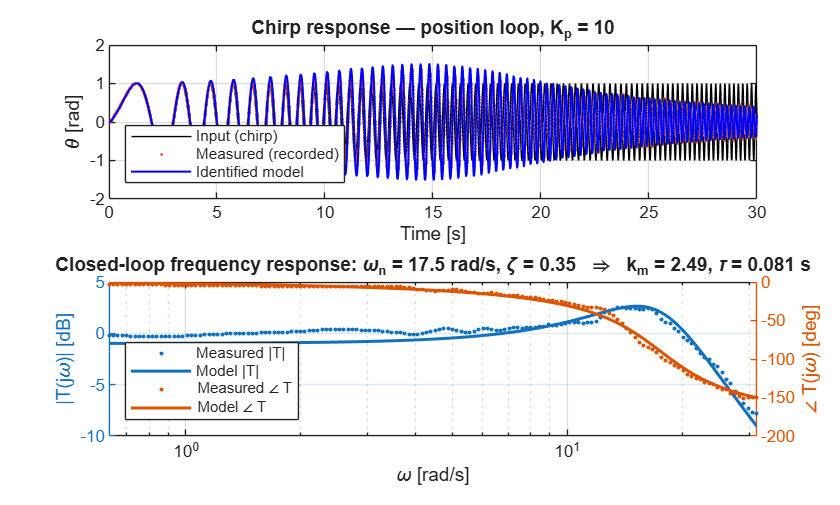


% time domain: recording vs. simulation of the identified model
Pid = G/s;
yCl = lsim(feedback(KpPos*Pid, 1), rS, tS);
figure
tiledlayout(2, 1, TileSpacing="compact")
nexttile
plot(tS, rS, "k"); hold on
plot(tS, yS, ".", MarkerSize=4, Color=[0.85 0.33 0.10])
plot(tS, yCl, "b", LineWidth=1); hold off
grid on; legend("Input (chirp)", "Measured" + sweepSuffix(runMode), "Identified model", Location="southwest")
title("Chirp response — position loop, K_p = " + KpPos); xlabel("Time [s]"); ylabel("\theta [rad]")

% frequency domain: empirical estimate from the sweep vs. identified model
nexttile
w = logspace(log10(2*pi*chirpF1), log10(2*pi*chirpF2), 150);
Gemp = spafdr(dataSweep, [], w);
[magE, phE] = bode(Gemp, w);
[magM, phM] = bode(Tcl, w);
yyaxis left
semilogx(w, 20*log10(squeeze(magE)), ".", w, 20*log10(squeeze(magM)), "-", LineWidth=1.5)
ylabel("|T(j\omega)| [dB]")
yyaxis right
semilogx(w, squeeze(phE), ".", w, squeeze(phM), "-", LineWidth=1.5)
ylabel("\angle T(j\omega) [deg]")
grid on; xlabel("\omega [rad/s]")
legend("Measured |T|", "Model |T|", "Measured \angle T", "Model \angle T", Location="southwest")
title(sprintf("Closed-loop frequency response: \\omega_n = %.1f rad/s, \\zeta = %.2f  \\Rightarrow  k_m = %.2f, \\tau = %.3f s", wnId, zetaId, km, tau))

## 5. Experiment 2 — velocity step, $K_p = 1,\ K_i = 0$

`HexaMotor_Velocity_Control_V02.slx`: square-wave reference of 15 rad/s (period 4 s, width 2 s, delay 1 s), stop time 7 s, PI set to $K_p=1,\ K_i=0$.

With proportional control only, the final-value theorem predicts a steady-state error $e_{\mathrm{ss}} = \frac{1}{1 + k_mK_p}$.

The simulated curve uses the identified $G(s)$, the 0.05 s measurement filter, the 200 Hz discrete controller and the ±12 V supply limit.

 
velAmp = 15; velStop = 7;
Kp1 = 1; Ki1 = 0;
if runMode == "hw"
    load_system(velModel);
    set_param(velModel, FixedStep=num2str(Ts));
    set_param(velModel + "/Discrete PID Controller", P=num2str(Kp1), I=num2str(Ki1));
    set_param(velModel + "/Discrete" + newline + "Pulse Generator", Amplitude=num2str(velAmp));
    stepP = runOnHexaMotor(velModel, velStop);
else
    stepP = virtualHexaMotor("velocity", "pulse", Ts, velStop, Kp1, Ki1, velAmp);
end
tP = stepP.time; rP = stepP.signals.values(:,1); yP = stepP.signals.values(:,2);
ySimP = simVelLoop(G, LPF, Kp1, Ki1, Ts, rP);

essTheory = 1/(1 + km*Kp1);
inSS = tP > 2.5 & tP < 3;
essMeas = 1 - mean(yP(inSS))/velAmp;
fprintf("Steady-state error: theory %.1f %%, simulated %.1f %%, %s %.1f %% \n", ...
    100*essTheory, 100*(1 - mean(ySimP(inSS))/velAmp), lower(measLabel), 100*essMeas);

Steady-state error: theory 28.6 %, simulated 28.6 %, emulated 28.9 % 


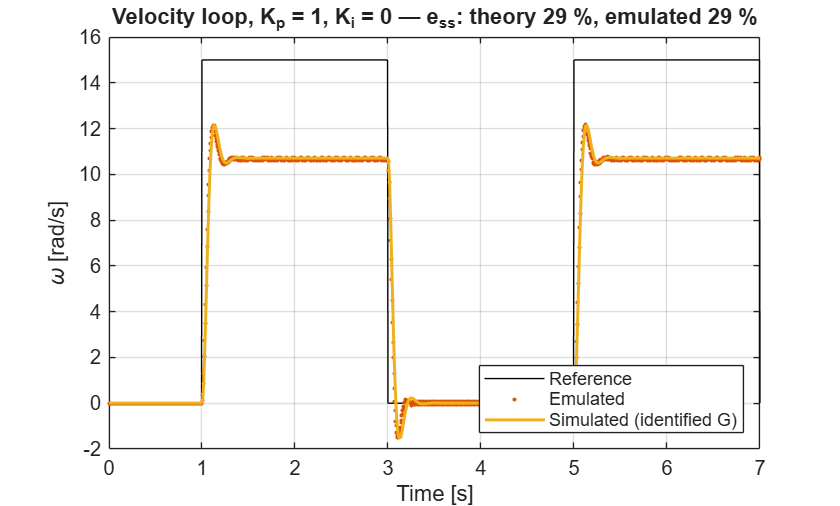


figure
plot(tP, rP, "k"); hold on
plot(tP, yP, ".", MarkerSize=6)
plot(tP, ySimP, LineWidth=1.5); hold off
grid on; legend("Reference", measLabel, "Simulated (identified G)", Location="southeast")
title(sprintf("Velocity loop, K_p = %g, K_i = %g — e_{ss}: theory %.0f %%, %s %.0f %%", Kp1, Ki1, 100*essTheory, lower(measLabel), 100*essMeas))
xlabel("Time [s]"); ylabel("\omega [rad/s]")

## 6. PI design for 30 % overshoot at 200 Hz

With $C(s) = K_p + K_i/s$ and the first-order motor, the velocity loop is


$$T(s) = \frac{k_m(K_ps + K_i)}{\tau s^2 + (1 + k_mK_p)s + k_mK_i} \quad\Rightarrow\quad \omega_n^2 = \frac{k_mK_i}{\tau},\qquad 2\zeta\omega_n = \frac{1 + k_mK_p}{\tau}$$


A single overshoot spec leaves a one-parameter family of gains, and the canonical formulas are only a first guess here: the PI zero, the 0.05 s measurement filter, the zero-order hold and the Forward-Euler integrator all add overshoot. So the design is done on the **exact discrete-time loop at** $T_s = 5$ ms:

- For every $K_p$ on a grid, solve for the $K_i$ that gives exactly the target overshoot.

- Keep $K_p \le (12 - 0.35)/15$ so the initial control effort for the 15 rad/s step does not saturate the 12 V supply.

- Pick the pair with the shortest 2 % settling time — the "best" 30 % response.

Along the iso-overshoot curve the settling time keeps falling as $K_p$ grows, so the optimum usually lands on the supply-voltage limit: the actuator, not the 200 Hz sample rate, is what limits speed. The printout checks the closed-loop bandwidth against $f_s$.

OS_target = 30;
uMax = 12; Vfric = 0.35;
KpMax = (uMax - Vfric)/velAmp;
[KpPI, KiPI, design] = designPI(G, LPF, Ts, OS_target, KpMax);
TclPI = design.Tcl;
infoPI = stepinfo(TclPI, SettlingTimeThreshold=0.02);
bwHz = bandwidth(TclPI)/(2*pi);
zetaPI = (1 + km*KpPI)/(2*sqrt(tau*km*KiPI));
fprintf("Best PI: Kp = %.4f, Ki = %.3f  ->  OS = %.1f %%, Tp = %.3f s, Ts(2%%) = %.3f s\n", ...
    KpPI, KiPI, infoPI.Overshoot, infoPI.PeakTime, infoPI.SettlingTime);

Best PI: Kp = 0.7767, Ki = 11.348  ->  OS = 30.0 %, Tp = 0.160 s, Ts(2%) = 0.515 s


fprintf("Canonical-denominator zeta = %.2f (a pure 2nd-order system would need zeta = %.2f for %g %% OS)\n", ...
    zetaPI, -log(OS_target/100)/sqrt(pi^2 + log(OS_target/100)^2), OS_target);

Canonical-denominator zeta = 0.97 (a pure 2nd-order system would need zeta = 0.36 for 30 % OS)


fprintf("Closed-loop bandwidth %.2f Hz  ->  fs/bw = %.0f (rule of thumb: > 10-20)\n", bwHz, fs/bwHz);

Closed-loop bandwidth 4.76 Hz  ->  fs/bw = 42 (rule of thumb: > 10-20)


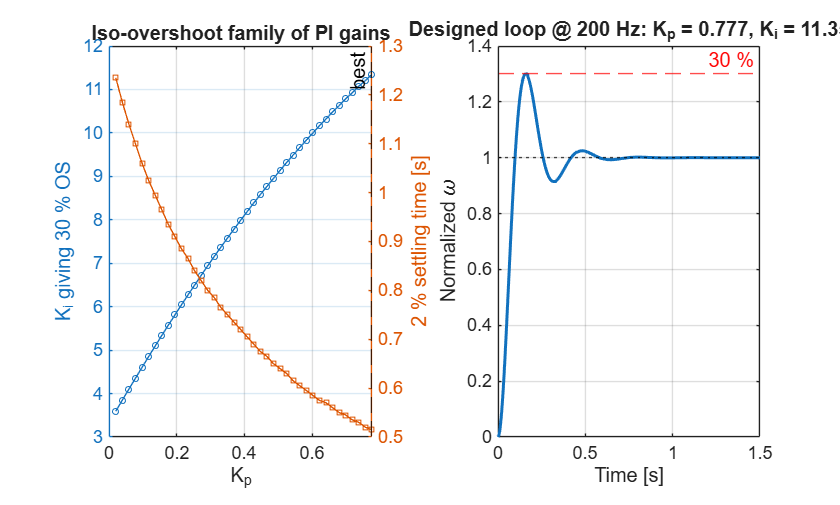


figure
tiledlayout(1, 2, TileSpacing="compact")
nexttile
yyaxis left;  plot(design.Kp, design.Ki, "-o", MarkerSize=3); ylabel("K_i giving " + OS_target + " % OS")
yyaxis right; plot(design.Kp, design.Tsettle, "-s", MarkerSize=3); ylabel("2 % settling time [s]")
xline(KpPI, "k--", "best", LabelHorizontalAlignment="left"); grid on; xlabel("K_p")
title("Iso-overshoot family of PI gains")
nexttile
[yd, td] = step(TclPI, 1.5);
stairs(td, yd, LineWidth=1.5); hold on
yline(1 + OS_target/100, "r--", OS_target + " %"); yline(1, "k:"); hold off
grid on; xlabel("Time [s]"); ylabel("Normalized \omega")
title(sprintf("Designed loop @ %g Hz: K_p = %.3f, K_i = %.2f", fs, KpPI, KiPI))

## 7. Experiment 3 — designed PI on the setup

Runs the same 15 rad/s square wave with the designed $K_p, K_i$ and overlays both experiments with their simulations from the identified transfer function.

 
if runMode == "hw"
    load_system(velModel);
    set_param(velModel + "/Discrete PID Controller", P=num2str(KpPI, 6), I=num2str(KiPI, 6));
    stepPI = runOnHexaMotor(velModel, velStop);
else
    stepPI = virtualHexaMotor("velocity", "pulse", Ts, velStop, KpPI, KiPI, velAmp);
end
tPI = stepPI.time; rPI = stepPI.signals.values(:,1); yPI = stepPI.signals.values(:,2);
ySimPI = simVelLoop(G, LPF, KpPI, KiPI, Ts, rPI);

osP = firstStepOS(tP, yP); osSimP = firstStepOS(tP, ySimP);
osPI = firstStepOS(tPI, yPI); osSimPI = firstStepOS(tPI, ySimPI);
fprintf("Overshoot  P (Kp=%g):  %s %.1f %%, simulated %.1f %% \n", Kp1, lower(measLabel), osP, osSimP);

Overshoot  P (Kp=1):  emulated 13.9 %, simulated 13.5 % 


fprintf("Overshoot  PI:         %s %.1f %%, simulated %.1f %%  (target %g %%)\n", lower(measLabel), osPI, osSimPI, OS_target);

Overshoot  PI:         emulated 28.4 %, simulated 32.8 %  (target 30 %)


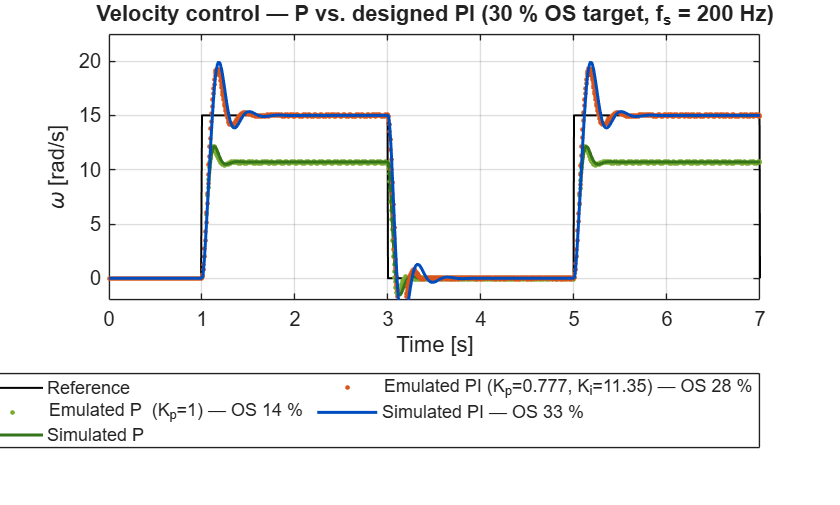


figure
plot(tPI, rPI, "k", LineWidth=1, DisplayName="Reference"); hold on
plot(tP, yP, ".", MarkerSize=7, Color=[0.47 0.67 0.19], DisplayName=sprintf(measLabel + " P  (K_p=%g) — OS %.0f %%", Kp1, osP))
plot(tP, ySimP, "-", LineWidth=1.5, Color=[0.20 0.45 0.10], DisplayName="Simulated P")
plot(tPI, yPI, ".", MarkerSize=7, Color=[0.85 0.33 0.10], DisplayName=sprintf(measLabel + " PI (K_p=%.3f, K_i=%.2f) — OS %.0f %%", KpPI, KiPI, osPI))
plot(tPI, ySimPI, "-", LineWidth=1.5, Color=[0.00 0.30 0.75], DisplayName=sprintf("Simulated PI — OS %.0f %%", osSimPI))
hold off
grid on; legend(Location="southoutside", NumColumns=2)
xlim([0 velStop]); ylim([-2 1.5*velAmp])
title(sprintf("Velocity control — P vs. designed PI (%g %% OS target, f_s = %g Hz)", OS_target, fs))
xlabel("Time [s]"); ylabel("\omega [rad/s]")

## Local functions

function str = sweepSuffix(runMode)
if runMode == "sim", str = " (emulated)"; elseif runMode == "rec", str = " (recorded)"; else, str = ""; end
end

function showLiveView(mdl, stopTime)
% Open the model diagram and its Scope so the audience sees the running model and the live
% external-mode response; the Scope time span covers the whole run.
open_system(mdl);
scopes = find_system(mdl, SearchDepth=1, BlockType="Scope");
for i = 1:numel(scopes)
    cfg = get_param(scopes{i}, "ScopeConfiguration");
    cfg.TimeSpan = num2str(stopTime);
    cfg.OpenAtSimulationStart = true;
    cfg.Visible = true;
end
drawnow
end

function sd = runOnHexaMotor(mdl, stopTime)
% Build, deploy and run a model on the HexaMotor in external mode (the "Monitor & Tune" button),
% wait for it to stop and return the Scope's logged ScopeData.
mdl = char(mdl);
load_system(mdl);
set_param(mdl, StopTime=num2str(stopTime), SimulationMode="external");
showLiveView(mdl, stopTime);                      % model diagram + live Scope during the run
evalin("base", "clear ScopeData");
fprintf("Building, deploying and running %s on the HexaMotor ...\n", mdl);
set_param(mdl, SimulationCommand="start");
t0 = tic;
while toc(t0) < 600 + 3*stopTime
    pause(0.5); drawnow
    if strcmp(get_param(mdl, "SimulationStatus"), "stopped") && evalin("base", "exist('ScopeData','var')")
        break
    end
end
if ~evalin("base", "exist('ScopeData','var')")
    error("No ScopeData received from %s. Check the USB cable, power switch and the Scope logging settings.", mdl);
end
sd = evalin("base", "ScopeData");
fprintf("Done: %d samples recorded.\n", numel(sd.time));
end

function y = simVelLoop(G, LPF, Kp, Ki, Ts, r)
% Discrete-time simulation of the velocity loop as implemented on the board:
% Forward-Euler PI at Ts, ZOH motor model, measurement filter, +/-12 V supply
% (minus the 0.35 V friction feed-forward).
sysd = c2d(ss(G*LPF), Ts, "zoh");
[A, B, C] = ssdata(sysd);
x = zeros(size(A, 1), 1); I = 0; uLim = 12 - 0.35;
y = zeros(size(r));
for k = 1:numel(r)
    y(k) = C*x;
    e = r(k) - y(k);
    u = min(max(Kp*e + I, -uLim), uLim);
    I = I + Ki*Ts*e;
    x = A*x + B*u;
end
end

function [KpBest, KiBest, d] = designPI(G, LPF, Ts, OS, KpMax)
% For each Kp find the Ki giving exactly OS percent overshoot on the discrete loop,
% then return the pair with the shortest 2 % settling time.
Gd = c2d(G*LPF, Ts, "zoh");
z = tf("z", Ts);
loop = @(Kp, Ki) feedback((Kp + Ki*Ts/(z - 1))*Gd, 1);
osOf = @(Kp, Ki) overshootOf(loop(Kp, Ki));
d.Kp = linspace(0.02, KpMax, 40); d.Ki = nan(size(d.Kp)); d.Tsettle = nan(size(d.Kp));
for i = 1:numel(d.Kp)
    Kp = d.Kp(i);
    f = @(Ki) osOf(Kp, Ki) - OS;
    lo = 1e-3;
    if f(lo) > 0, continue, end            % P alone already overshoots more than the target
    hi = 1;
    while f(hi) < 0 && hi < 1e4, lo = hi; hi = 2*hi; end
    if hi >= 1e4, continue, end
    d.Ki(i) = fzero(f, [lo hi]);
    info = stepinfo(loop(Kp, d.Ki(i)), SettlingTimeThreshold=0.02);
    d.Tsettle(i) = info.SettlingTime;
end
[~, iBest] = min(d.Tsettle);
KpBest = d.Kp(iBest); KiBest = d.Ki(iBest);
d.Tcl = loop(KpBest, KiBest);
end

function os = overshootOf(sys)
if ~isstable(sys), os = 1e3; return, end
ws = warning("off"); % trial gains near instability may not settle within the default horizon
cleanup = onCleanup(@() warning(ws));
info = stepinfo(sys);
os = info.Overshoot;
end

function os = firstStepOS(t, y)
% Overshoot [%] of the first rising edge (t = 1 s) relative to the value reached at the end of the pulse.
win = t >= 1 & t < 3;
yss = mean(y(t > 2.6 & t < 3));
os = 100*(max(y(win)) - yss)/yss;
end

function sd = virtualHexaMotor(loop, refType, Ts, stopTime, Kp, Ki, refPar)
% Nonlinear stand-in for the HexaMotor + Simulink model, used when runMode = "sim".
% The "true" motor below is unknown to the identification.
kmT = 2.42; tauT = 0.0705;        % true first-order motor [rad/s/V], [s]
Vstick = 0.32; Vcoul = 0.28;      % static / kinetic friction, voltage-equivalent [V]
Vcomp = 0.35;                     % friction feed-forward in the model [V]
enc = 2*pi/979.62;                % encoder resolution at the gearbox output [rad]
Tf = 0.05;                        % Filtered Derivative time constant [s]
t = (0:round(stopTime/Ts))'*Ts;
if refType == "chirp"             % Simulink Chirp Signal: f(t) = f1 + (f2-f1) t/T
    f1 = refPar(1); f2 = refPar(2); T = refPar(3);
    r = sin(2*pi*(f1 + (f2 - f1)/(2*T)*t).*t);
else                              % Pulse: 4 s period, 2 s width, 1 s delay
    r = refPar(1)*(t >= 1 & mod(t - 1, 4) < 2);
end
nSub = 20; dt = Ts/nSub;
theta = 0; w = 0; I = 0; velF = 0; thPrev = 0;
y = zeros(size(t));
for k = 1:numel(t)
    thq = enc*round(theta/enc);
    velF = velF + Ts/Tf*((thq - thPrev)/Ts - velF);
    thPrev = thq;
    if loop == "position", y(k) = thq; else, y(k) = velF; end
    e = r(k) - y(k);
    u = Kp*e + I;
    I = I + Ki*Ts*e;
    v = u + Vcomp*sign(u);
    v = round(min(max(v, -12), 12)/12*255)*12/255;   % 8-bit PWM, 12 V supply
    for j = 1:nSub
        if w == 0 && abs(v) <= Vstick, continue, end
        dir = sign(w); if dir == 0, dir = sign(v); end
        wNew = w + dt*(kmT*(v - Vcoul*dir) - w)/tauT;
        if w ~= 0 && sign(wNew) ~= sign(w) && abs(v) <= Vstick, wNew = 0; end
        theta = theta + dt*(w + wNew)/2;
        w = wNew;
    end
end
sd.time = t;
sd.signals.values = [r y];
end